# **NUNNA LEEKHITH SRI KRISHNA**

## **Uncovering Hidden Climate Adaptation Patterns **

## **Using Clustering and Dimensionality Reduction**

**Size and Feactures of data set**

data = readtable("C:\Users\leekh\OneDrive - Amrita vishwa vidyapeetham\Git\5_climate_change_impact_on_agriculture_2024\climate_change_impact_on_agriculture_2024.csv");

% Display first few rows
disp("📊 Sample Data:");

📊 Sample Data:


disp(head(data));

    Year       Country             Region             Crop_Type      Average_Temperature_C    Total_Precipitation_mm    CO2_Emissions_MT    Crop_Yield_MT_per_HA    Extreme_Weather_Events    Irrigation_Access_    Pesticide_Use_KG_per_HA    Fertilizer_Use_KG_per_HA    Soil_Health_Index       Adaptation_Strategies       Economic_Impact_Million_USD
    ____    _____________    ___________________    _____________    _____________________    ______________________    ________________    ____________________    ______________________    __________________    ________


% Display feature names
disp("🧠 Feature Names:");

🧠 Feature Names:


disp(data.Properties.VariableNames);

    {'Year'}    {'Country'}    {'Region'}    {'Crop_Type'}    {'Average_Temperature_C'}    {'Total_Precipitation_mm'}    {'CO2_Emissions_MT'}    {'Crop_Yield_MT_per_HA'}    {'Extreme_Weather_Events'}    {'Irrigation_Access_'}    {'Pesticide_Use_KG_per_HA'}    {'Fertilizer_Use_KG_per_HA'}    {'Soil_Health_Index'}    {'Adaptation_Strategies'}    {'Economic_Impact_Million_USD'}




% Display variable types (class of each column)
disp("🔍 Feature Types:");

🔍 Feature Types:


summary(data)

Variables:

    Year: 10000×1 double

        Values:

            Min         1990  
            Median      2007  
            Max         2024  

    Country: 10000×1 cell array of character vectors

    Region: 10000×1 cell array of character vectors

    Crop_Type: 10000×1 cell array of character vectors

    Average_Temperature_C: 10000×1 double

        Values:

            Min         -4.99 
            Median     15.175 
            Max            35 

    Total_Precipitation_mm: 10000×1 double

        Values:

            Min        200.15 
            Median     1611.2 
            Max        2999.7 

    CO2_Emissions_MT: 10000×1 double

        Values:

            Min          0.5  
            Median      15.2  
            Max           30  

    Crop_Yield_MT_per_HA: 10000×1 double

        Values:

            Min         0.45  
    

**Clean & Normalize for PCA**

*Remove target/adaptation label if still present*

% (Assume 'Adaptation_Strategy' is the target column – change if needed)
if any(strcmp(data.Properties.VariableNames, 'Adaptation_Strategy'))
    data.Adaptation_Strategy = [];
end

*Handle categorical data (encode them as numbers)*

data = convertvars(data, @iscategorical, 'cell'); % Convert categoricals to cell (if any)
data = convertvars(data, @isstring, 'cell');      % Convert strings to cell
data = convertvars(data, @iscell, 'categorical'); % All strings/cells → categorical
data = varfun(@double, data);                     % Convert all categorical → numeric

*Normalize (Z-score)*

X = table2array(data);            % Convert to pure matrix
X_norm = zscore(X);               % Normalize

% Check dimensions
fprintf("✅ Final matrix size: %d samples x %d features\n", size(X_norm,1), size(X_norm,2));

✅ Final matrix size: 10000 samples x 15 features


**Apply PCA & Visualize in 2D**

% Run PCA
[coeff, score, ~, ~, explained] = pca(X_norm);

% Display how much variance first 2 components explain
fprintf("⚡ PC1 explains: %.2f%%\n", explained(1));

⚡ PC1 explains: 12.44%


fprintf("⚡ PC2 explains: %.2f%%\n", explained(2));

⚡ PC2 explains: 7.20%


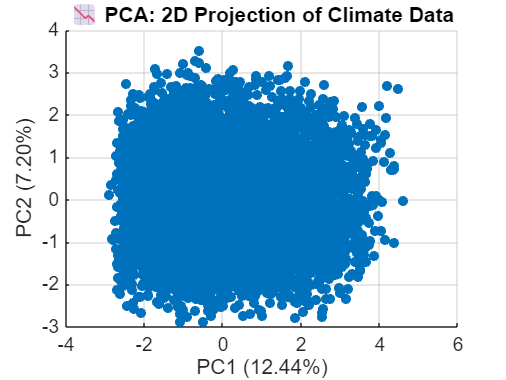


% Plot PCA-reduced data (first 2 principal components)
figure;
scatter(score(:,1), score(:,2), 25, 'filled');
title('📉 PCA: 2D Projection of Climate Data');
xlabel(sprintf('PC1 (%.2f%%)', explained(1)));
ylabel(sprintf('PC2 (%.2f%%)', explained(2)));
grid on;

**Apply t-SNE for Better Cluster Visualization**

% Set random seed for consistent output
rng(42);

% Run t-SNE on normalized data
Y_tsne = tsne(X_norm, ...
              'NumDimensions', 2, ...
              'Perplexity', 50, ...      % Try 30–50 for large datasets
              'Exaggeration', 4, ...
              'LearnRate', 1000, ...
              'Verbose', 1);

|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    2.621301e+01 |    2.173705e-07 |
|       40 |    2.549734e+01 |    1.331953e-03 |
|       60 |    2.550012e+01 |    2.634355e-06 |
|       80 |    2.550039e+01 |    7.571228e-06 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    4.989905e+00 |    1.188972e-04 |
|      120 |    4.132310e+00 |    4.491186e-05 |
|      140 |    3.974825e+00 |    8.446668e-05 |
|      160 |    3.881011e+00 |    2.980933e-05 |
|      180 |    3.818606e+00 |    2.749106e-05 |
|      200 |    3.773438e+00 |    3.083561e-05 |
|      220 |    3.7

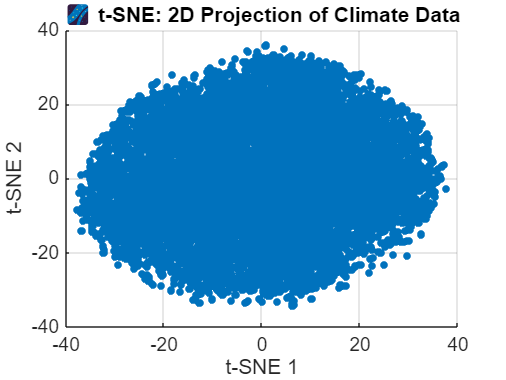


% Plot t-SNE result
figure;
scatter(Y_tsne(:,1), Y_tsne(:,2), 15, 'filled');
title('🌌 t-SNE: 2D Projection of Climate Data');
xlabel('t-SNE 1');
ylabel('t-SNE 2');
grid on;

**jump to UMAP (it’s spicier than t-SNE for structure-preserving)**

UMAP Setup in MATLAB

which run_umap

C:\Users\leekh\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\Uniform Manifold Approximation and Projection (UMAP)\umap\run_umap.m


Run UMAP on Normalized Data

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 12 assigned logical cores for nn_descent_tasks, sgd_tasks
 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
min=-11.50, max=1.50
mins:	-1.6946     -1.5733      -1.663     -1.5882     -1.7643     -1.7534     -1.7168      -1.793     -1.5733     -1.7407     -1.7222     -1.7402     -1.7281      -1.426      -1.511
maxs:	1.677      1.5583      1.7506      1.5484      1.7231      1.7242      1.7176      2.7646      1.5854      1.7216      1.7276      1.7421      1.7379      1.4029      4.0334
UMAP(method=MEX, n_neighbors=15, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, sprea

ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0151 0.0183 0.0204 0.0221 0.0235 0.0249 0.0264 0.0282 0.0308 0.0412]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


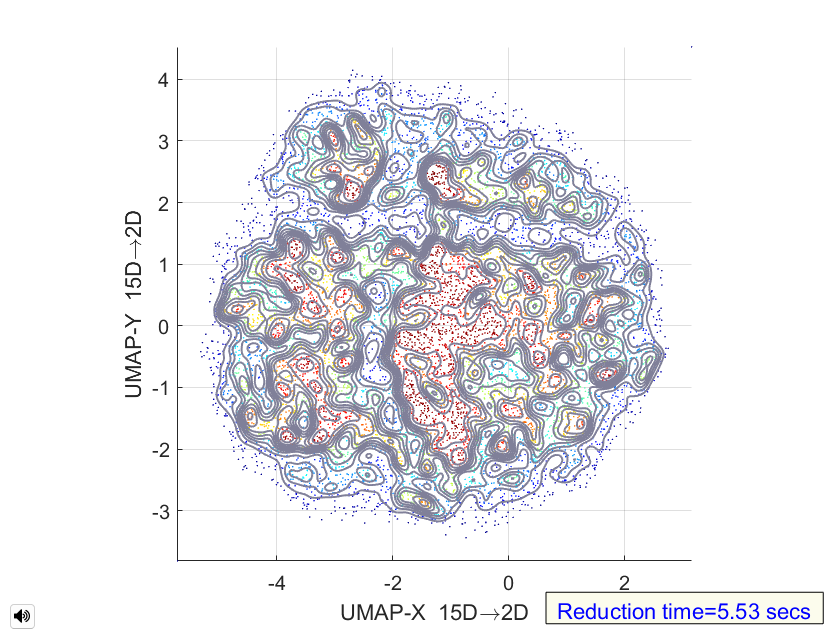

UMAP reduction finished (cost 5.84 secs)
 Finished basic (ub) reduction


% Run UMAP to reduce dimensions to 2
[umapOut, umapStruct] = run_umap(X_norm, 'n_components', 2);

Plot the UMAP Projection

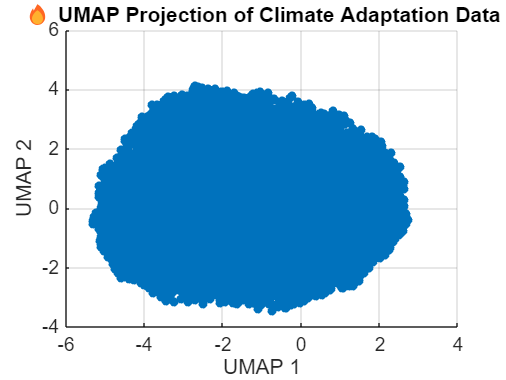

figure;
scatter(umapOut(:,1), umapOut(:,2), 20, 'filled');
xlabel('UMAP 1');
ylabel('UMAP 2');
title('🔥 UMAP Projection of Climate Adaptation Data');
grid on;

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 12 assigned logical cores for nn_descent_tasks, sgd_tasks
 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=15, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0019 0.0023 0.0026 0.0029 0.0032 0.0035 0.0038 0.0041 0.0046 0.0069]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


UMAP reduction finished (cost 8.11 secs)
 Finished basic (ub) reduction


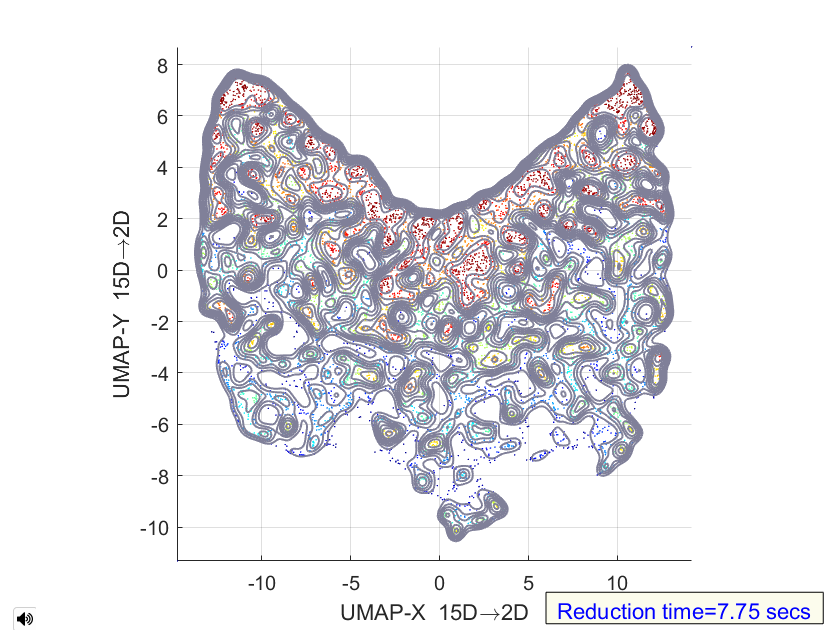

[embedding, umapStruct, clusterIdentifiers] = run_umap(X); 

reducedData = embedding;

**Clustering in MATLAB**

*K-Means Clustering*

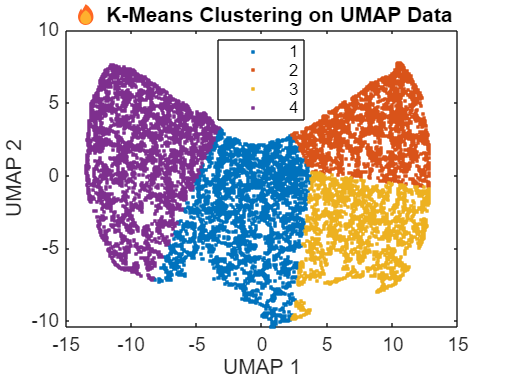

k = 4; % try different values like 3, 5, 6
[idx_kmeans, C] = kmeans(reducedData, k);

figure;
gscatter(reducedData(:,1), reducedData(:,2), idx_kmeans);
title('🔥 K-Means Clustering on UMAP Data');
xlabel('UMAP 1'); ylabel('UMAP 2');

Hierarchical Clustering

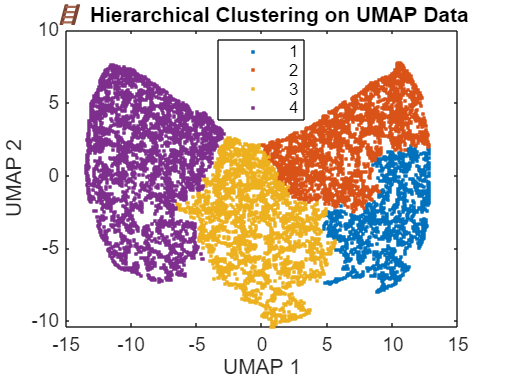

Z = linkage(reducedData, 'ward');
idx_hier = cluster(Z, 'Maxclust', 4);

figure;
gscatter(reducedData(:,1), reducedData(:,2), idx_hier);
title('🪜 Hierarchical Clustering on UMAP Data');
xlabel('UMAP 1'); ylabel('UMAP 2');

DBSCAN

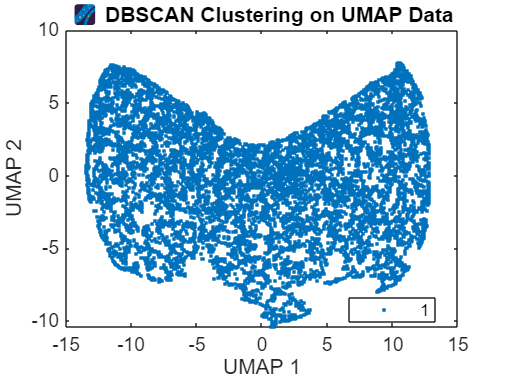

epsilon = 0.5;
minPts = 10;
idx_dbscan = dbscan(reducedData, epsilon, minPts);

figure;
gscatter(reducedData(:,1), reducedData(:,2), idx_dbscan);
title('🌌 DBSCAN Clustering on UMAP Data');
xlabel('UMAP 1'); ylabel('UMAP 2');

Gaussian Mixture Model (GMM)

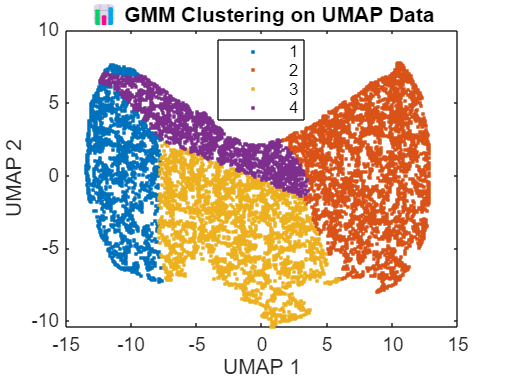

gmmModel = fitgmdist(reducedData, 4);
idx_gmm = cluster(gmmModel, reducedData);

figure;
gscatter(reducedData(:,1), reducedData(:,2), idx_gmm);
title('📊 GMM Clustering on UMAP Data');
xlabel('UMAP 1'); ylabel('UMAP 2');

Spectral Clustering (using built-in MATLAB Graph functions)

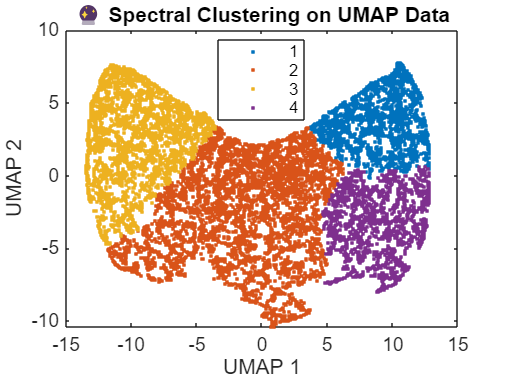

% Use similarity graph (you can tune neighbors)
[idx_spec, ~] = spectralcluster(reducedData, 4);

figure;
gscatter(reducedData(:,1), reducedData(:,2), idx_spec);
title('🔮 Spectral Clustering on UMAP Data');
xlabel('UMAP 1'); ylabel('UMAP 2');

#### MATLAB script: **K-Means, DBSCAN, GMM, Hierarchical, Spectral Clustering** — all applied on your 2D

% 📌 Make sure reducedData (from UMAP/t-SNE/PCA) is defined
% e.g., reducedData = embedding;

% Auto set seed for reproducibility
rng(42); 

% Create figure
figure('Name','Clustering Results','NumberTitle','off');


%% 📥 Load Data
data = readtable('climate_change_impact_on_agriculture_2024.csv');
data = rmmissing(data);

% 🔍 Select only numeric predictors
selectedColumns = {'Average_Temperature_C', 'Total_Precipitation_mm', ...
    'CO2_Emissions_MT', 'Crop_Yield_MT_per_HA', 'Extreme_Weather_Events', ...
    'Irrigation_Access_', 'Pesticide_Use_KG_per_HA', ...
    'Fertilizer_Use_KG_per_HA', 'Soil_Health_Index'};

X = table2array(data(:, selectedColumns));

% 🔧 Normalize
mu = mean(X);
sigma = std(X);
X_norm = (X - mu) ./ sigma;

% 📉 PCA
[coeff, score] = pca(X_norm);
reducedData = score(:,1:2); % Top 2 PCs

% 🧠 KMeans
k = 5;
[idx_kmeans, C_kmeans] = kmeans(reducedData, k);

% 📦 GMM
gmm = fitgmdist(reducedData, k, 'RegularizationValue', 0.1);


%% 1️⃣ K-Means
subplot(2,3,1)
k = 4; % You can change this
kIdx = kmeans(reducedData, k);
gscatter(reducedData(:,1), reducedData(:,2), kIdx);
title('K-Means Clustering')
xlabel('Dim 1'), ylabel('Dim 2')

%% 2️⃣ DBSCAN
subplot(2,3,2)
epsilon = 0.8;
minPts = 10;
dbIdx = dbscan(reducedData, epsilon, minPts);
gscatter(reducedData(:,1), reducedData(:,2), dbIdx);
title('DBSCAN Clustering')
xlabel('Dim 1'), ylabel('Dim 2')

%% 3️⃣ Gaussian Mixture Model (GMM)
subplot(2,3,3)
gmm = fitgmdist(reducedData, k);

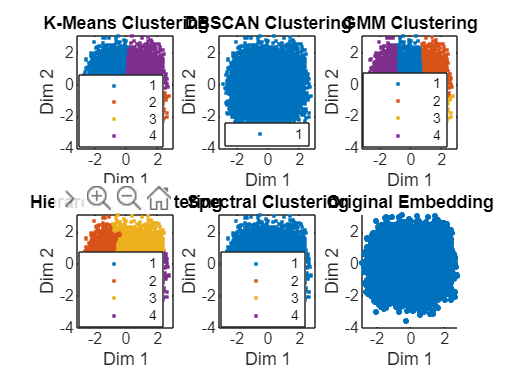

gmmIdx = cluster(gmm, reducedData);
gscatter(reducedData(:,1), reducedData(:,2), gmmIdx);
title('GMM Clustering')
xlabel('Dim 1'), ylabel('Dim 2')

%% 4️⃣ Hierarchical Clustering
subplot(2,3,4)
linkTree = linkage(reducedData, 'ward');
hIdx = cluster(linkTree, 'maxclust', k);
gscatter(reducedData(:,1), reducedData(:,2), hIdx);
title('Hierarchical Clustering')
xlabel('Dim 1'), ylabel('Dim 2')

%% 5️⃣ Spectral Clustering
subplot(2,3,5)
W = pdist2(reducedData, reducedData);
sigma = 1;
S = exp(-W.^2 / (2*sigma^2));
D = diag(sum(S,2));
L = D - S;
[eigVecs, ~] = eigs(L, k, 'smallestabs');
specIdx = kmeans(eigVecs, k);
gscatter(reducedData(:,1), reducedData(:,2), specIdx);
title('Spectral Clustering')
xlabel('Dim 1'), ylabel('Dim 2')

%% 6️⃣ Ground Truth or Random Reference (Optional)
subplot(2,3,6)
scatter(reducedData(:,1), reducedData(:,2), 10, 'filled');
title('Original Embedding')
xlabel('Dim 1'), ylabel('Dim 2')

data = readtable('climate_change_impact_on_agriculture_2024.csv');
disp(data.Properties.VariableNames)

    {'Year'}    {'Country'}    {'Region'}    {'Crop_Type'}    {'Average_Temperature_C'}    {'Total_Precipitation_mm'}    {'CO2_Emissions_MT'}    {'Crop_Yield_MT_per_HA'}    {'Extreme_Weather_Events'}    {'Irrigation_Access_'}    {'Pesticide_Use_KG_per_HA'}    {'Fertilizer_Use_KG_per_HA'}    {'Soil_Health_Index'}    {'Adaptation_Strategies'}    {'Economic_Impact_Million_USD'}



### GUI Code Block

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 12 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=15, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0103 0.0128 0.0145 0.0159 0.0174 0.0187 0.0198 0.0212 0.0230 0.0323]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


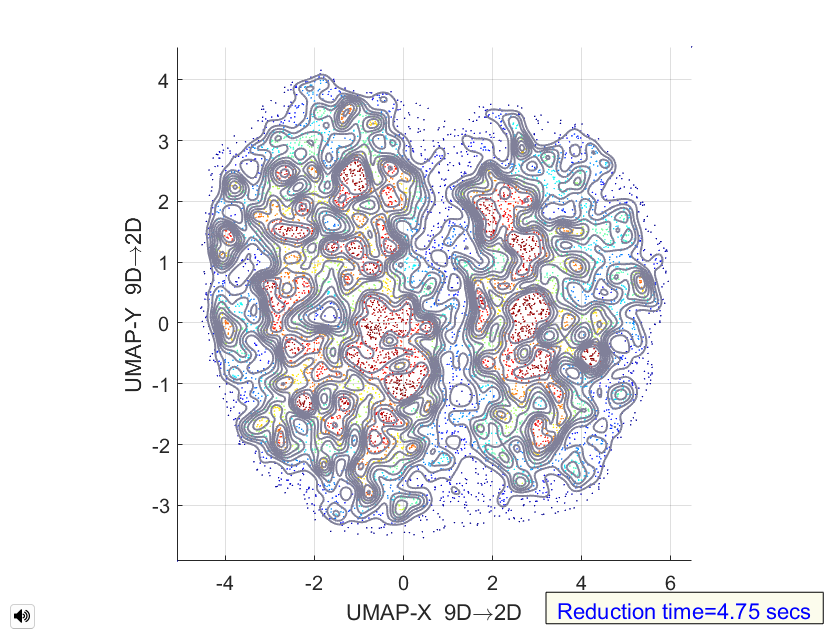

UMAP reduction finished (cost 5.01 secs)
 Finished basic (ub) reduction


%% 🌍 Climate Adaptation Cluster Predictor GUI
clc; clear; close all;

%% 📥 Load and Normalize Data
data = readtable('climate_change_impact_on_agriculture_2024.csv');
data = rmmissing(data);

selectedColumns = {'Average_Temperature_C', 'Total_Precipitation_mm', 'CO2_Emissions_MT', ...
    'Crop_Yield_MT_per_HA', 'Extreme_Weather_Events', 'Irrigation_Access_', ...
    'Pesticide_Use_KG_per_HA', 'Fertilizer_Use_KG_per_HA', 'Soil_Health_Index'};

X = table2array(data(:, selectedColumns));
mu = mean(X);
sigma = std(X);
X_norm = (X - mu) ./ sigma;

%% 🔥 UMAP Dimensionality Reduction
[reduction, umapStruct] = run_umap(X_norm, 'n_components', 2);

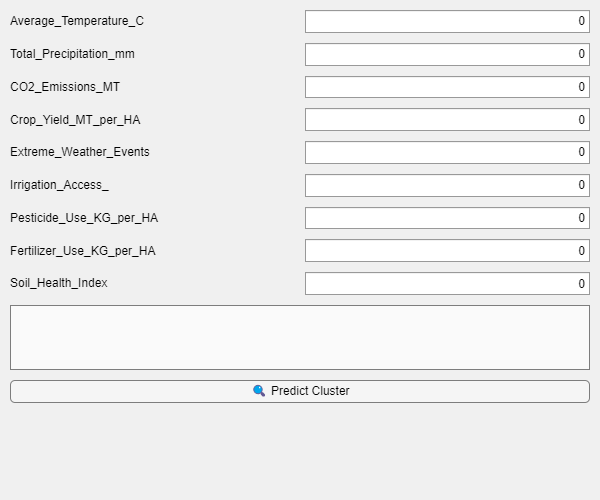

reducedData = reduction;

%% 🔗 KMeans Clustering
k = 5;
[idx_kmeans, C_kmeans] = kmeans(reducedData, k, 'Replicates', 10);

%% 📦 GMM Clustering
gmm = fitgmdist(reducedData, k, 'RegularizationValue', 0.1);
idx_gmm = cluster(gmm, reducedData);

%% 🧑‍💻 GUI Setup
f = uifigure('Name', 'Climate Adaptation Cluster Predictor', 'Position', [100 100 600 500]);
uigrid = uigridlayout(f, [length(selectedColumns)+2, 2]);
uigrid.RowHeight = repmat({'fit'}, 1, length(selectedColumns)+2);
uigrid.ColumnWidth = {'1x','1x'};

fields = cell(length(selectedColumns), 1);
for i = 1:length(selectedColumns)
    uilabel(uigrid, 'Text', selectedColumns{i});
    fields{i} = uieditfield(uigrid, 'numeric');
end

resultArea = uitextarea(uigrid, 'Editable', 'off');
resultArea.Layout.Row = length(selectedColumns)+1;
resultArea.Layout.Column = [1 2];

predictBtn = uibutton(uigrid, 'Text', '🔍 Predict Cluster');
predictBtn.Layout.Row = length(selectedColumns)+2;
predictBtn.Layout.Column = [1 2];

% Assign fixed callback
predictBtn.ButtonPushedFcn = @(btn,event) predictClusterCallback(f, fields, mu, sigma, selectedColumns, C_kmeans, gmm, resultArea);


%% ✅ Final Callback Function
function predictClusterCallback(f, fields, mu, sigma, selectedColumns, C_kmeans, gmm, resultArea)
try
    % Extract and validate input
    userInput = zeros(1, length(fields));
    for i = 1:length(fields)
        val = fields{i}.Value;  % already numeric
        if isempty(val) || ~isnumeric(val)
            uialert(f, sprintf('Invalid input in %s', selectedColumns{i}), 'Input Error');
            return;
        end
        userInput(i) = val;

    end

    % Normalize user input
    userInputNorm = (userInput - mu) ./ sigma;

    % Run UMAP without displaying figures (must have at least 2 rows)
    userUMAP = run_umap([userInputNorm; zeros(10, length(userInputNorm))], ...
        'n_components', 2, ...
        'display', 'none');
    X_new_2D = userUMAP(1,:);  % Only take the first row

    % Predict cluster from KMeans and GMM
    [~, pred_kmeans] = min(vecnorm(C_kmeans - X_new_2D, 2, 2));
    pred_gmm = cluster(gmm, X_new_2D);

    % Show results
    resultArea.Value = sprintf("🎯 KMeans Cluster: %d\n🎯 GMM Cluster: %d", ...
        pred_kmeans, pred_gmm);

catch ME
    if isvalid(resultArea)
        resultArea.Value = sprintf("❌ Error: %s", ME.message);
    else
        disp("⚠️ GUI was closed before prediction finished.");
    end
end
end